## Illustrazione grafica del punto di break even

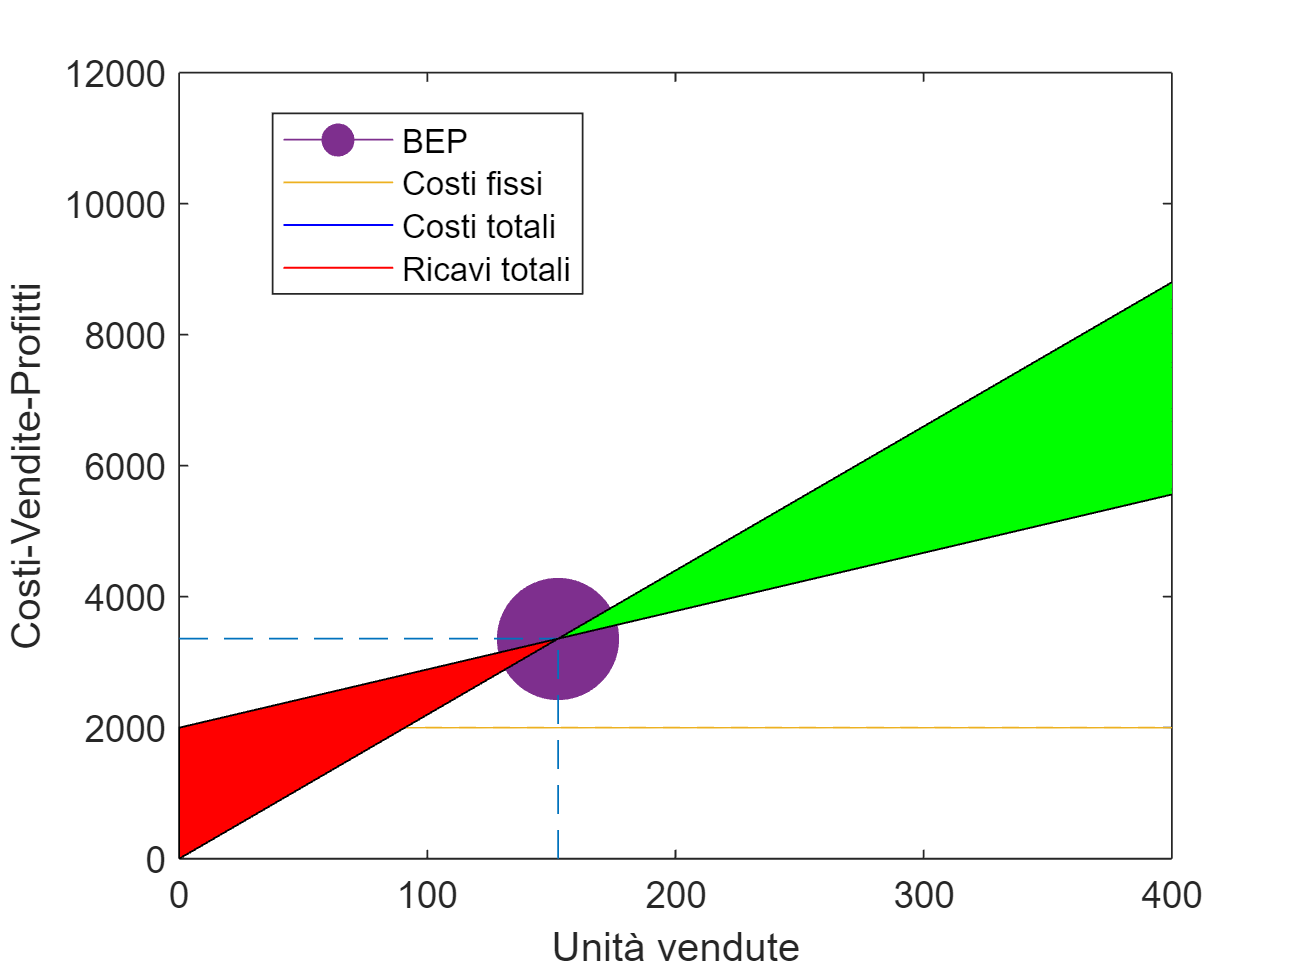



a=8.9;
b=22;
c=2000;
aree=true;
linee=true;

X=0:0.1:1000;
Y1=0*X+c; %Costi fissi
Y2=a*X+c; %Costi totali
Y3=b*X; %Ricavi totali

Y_int=abs(Y2-Y3);
[m,i]=min(Y_int);
assert(X(i)<400,"non è possibile trovare il punto di break even nell'intervallo");

figure
plot(X(i),Y2(i),'Marker', '.', 'MarkerSize', 100, 'Color',[0.4940 0.1840 0.5560],'DisplayName', 'BEP');
hold on
plot(X,Y1,'Color',[0.9290 0.6940 0.1250],'DisplayName', 'Costi fissi')
plot(X,Y2,'b','DisplayName', 'Costi totali')
plot(X,Y3,'r','DisplayName', 'Ricavi totali')
legend(Location="best")
hleg = legend('show'); 

if linee==true
plot([X(i) X(i)],[0 Y2(i)],'--','Color',[0 0.4470 0.7410])
hleg.String(end) = [];
plot([0 X(i)],[Y2(i) Y2(i)],'--','Color',[0 0.4470 0.7410])
hleg.String(end) = [];
end

if aree==true
Xsup=X(:,i:end);
Y2sup=Y2(:,i:end);
Y3sup=Y3(:,i:end);
patch([Xsup fliplr(Xsup)], [Y2sup fliplr(Y3sup)], 'g')
hleg.String(end) = [];
Xinf=X(:,1:i);
Y2inf=Y2(:,1:i);
Y3inf=Y3(:,1:i);
patch([Xinf fliplr(Xinf)], [Y2inf fliplr(Y3inf)], 'r')
hleg.String(end) = [];
end

hold off
xlim([0 400])
ylim([0 12000])
xlabel('Unità vendute')
ylabel('Costi-Vendite-Profitti')


disp('-----------')

-----------


disp(['Unita da vendere per Break Even points=' num2str(X(i))] )

Unita da vendere per Break Even points=152.7


disp('-----------')

-----------
